clc; clear; close all;

% Data Generation       
max_iter = 1000;
m = 51;
x = linspace(0,1,m);
noise = normrnd(0, 0.4, size(x));
y = 15*x+5+noise;



%intial guesses for w0 & w1
w0 = rand(1);
w1 = rand(1);
alp = 1.5;
j = zeros(max_iter,1);
j(1) = 0.5/m*sum((y-w1*x-w0).^2);
err = 1;
iter = 1;

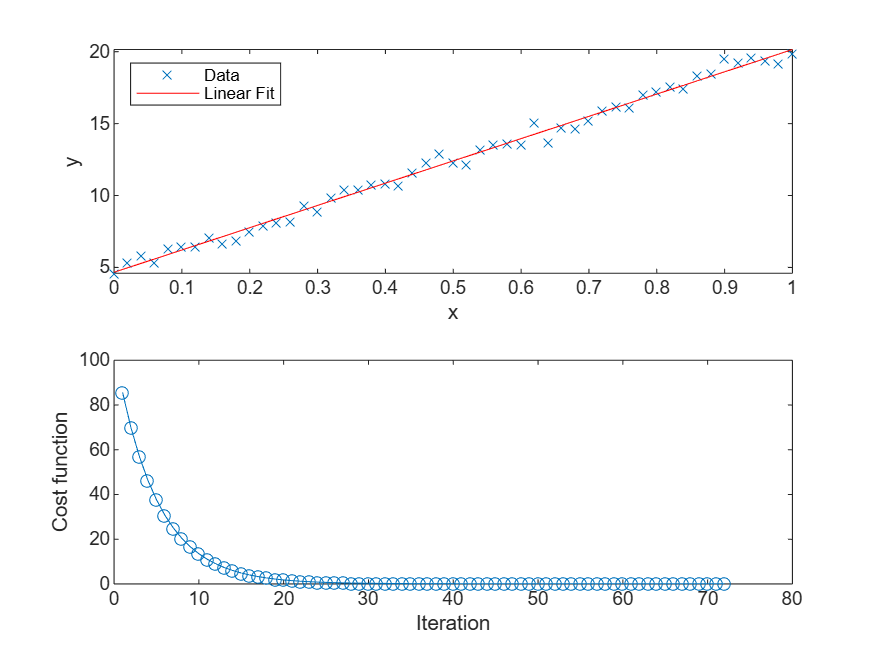

figure;
while err > 1.e-5 && iter < max_iter  
    yh= w1*x +w0;
    dw0 = -alp*sum(yh -y)/m;
    dw1 = -alp*sum((yh-y).*x)/m;

    w0 = w0 + dw0;
    w1 = w1+dw1;

    iter = iter + 1;
    j(iter) = 0.5/m*sum((y - w1*x-w0).^2);

    if iter > 1
        err = abs(j(iter)- j(iter-1));
    else
        err = 1
    end

    clf;
    subplot(2,1,1);
    plot(x,y,'x', 'DisplayName', 'Data');
    hold on;
    plot(x, yh, 'r', 'DisplayName', 'Linear Fit');
    xlabel('x'); ylabel('y');
    legend('Location','northwest');
    hold off;

    subplot(2,1,2);
    plot(1:iter, j(1:iter), '-o');
     xlabel('Iteration'); ylabel('Cost function');

    drawnow;
end


disp(['w0: ', num2str(w0)]);

w0: 4.6783


disp(['w1: ', num2str(w1)]);

w1: 15.4945
